%% clear workspace
clear variables
close all
clc

## load in data

addpath(genpath('C:\Users\Xiangnan\Documents\MyGitRepo\FLImBrushDataProcessingTool\Preprocessing_APD'))
FB = load('D:\LoaclData\5ALAFLImTest\Subject031_20210804\DeconResult\2021_08_04_neuro031_05_S.mat');

## get raw data

WF = FB.Ch1DataObj.rawData;
WF = WF-mean(WF(450:500,:));

## plot raw data

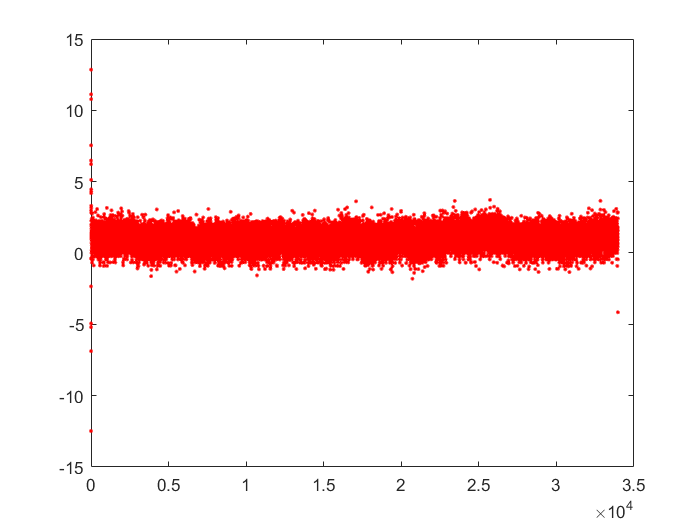

figure
M = max(WF);
S = WF(313,:)-WF(325,:);
P = S./M*100;
figure;plot(P,'r.')

mean(P)

ans = 0.9559

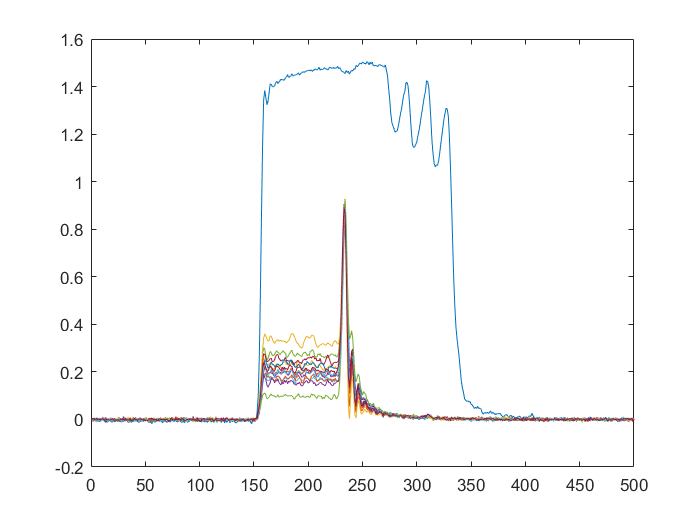

plot(WF(:,1:2500:end))